# Classifying Movies with Deep Learning

In this project, we will create a database of movies, with fictional ratings. We will then create a set of viewers. We will then try to predict if a viewer would choose to watch a particular movie. We will use deep learning with MATLAB’s pattern recognition network, `patternnet`.

## Generating a Movie Database

We first need to come up with a method for characterizing movies. In this projects, The movie database will have five characteristics.


$$\matrix{
\text{Characteristic}    	& \text{Value} \cr
\text{Name}			& \text{String} \cr
\text{Genre}			& \text{Type of movie} \cr
\text{Rating}			& \text{Average viewer rating} \cr
\text{Quality}			& \text{Number of stars} \cr
\text{Length}			& \text{Minute duration} \cr
\text{MPAA Rating}			& \text{MPAA Rating (PG, PG-13, R)} \cr

}$$


Next, we will create a MATLAB function, `MovieDatabase.m`, to create a database of movies. Running the code below creates a database of movies in a data structure. The length and ratings are added here.

d    = MovieDatabase('Movies.txt')

d =       name: {1x100 cell}
    rating: [2 3 1 4 4 5 5 5 3 1 3 2 2 2 1 4 4 3 2 5 3 5 5 2 3 2 4 4 4 1 5 1 3 4 4 2 4 5 2 1 2 2 2 5 1 3 1 5 1 3 5 2 1 2 2 2 2 5 4 5 3 5 1 4 5 2 5 4 5 3 4 2 2 2 3 5 2 3 5 4 5 2 5 4 2 3 2 3 5 1 5 5 2 3 3 4 4 4 2 3]
    length: [1x100 double]
     genre: {1x100 cell}
      mPAA: {1x100 cell}


Here are the first few movies:

d.name'

ans =     '2001: A Space Odyssey'
    'A Star is Born'
    'Alien'
    'Aliens'
    'Amadeus'
    'Apocalypse Now'
    'Apollo 13'
    'Back to the Future'
    'Bambi'
    'Barry Lyndon'
    'Ben-Hur'
    'Blade Runner'
    'Blazing Saddles'
    'Bohemian Rhapsody'
    'Bonnie and Clyde'
    'Breakfast at Tiffany's'
    'Cabaret'
    'Carousel'
    'Center Stage'
    'Chinatown'
    'Citizen Kane'
    'Das Boot'
    'Die Hard'
    'Dr. Strangelove'
    'Easy Rider'
    'Fail Safe'
    'Fantasia'
    'Fargo'
    'Forbidden Planet'
    'Forrest Gump'
    'Gettysburg'
    'Gladiator'
    'Gone with the Wind'
    'Good Will Hunting'
    'Green Book'
    'Harry Potter the Sorcerer's Stone'
    'Henry V'
    'Inception'
    'It's a Wonderful Life'
    'Jaws'
    'Jurassic Park'
    'King Kong'
    'Lawrence of Arabia'
    'LBJ'
    'M*A*S*H'
    'Mad Max'
    'Marooned'
    'Mary Poppins'
    'Mulan'
    'North by Northwest'
    'On the Waterfront'
    'Paths of Glory'
    'Platoon'
    'Por

## Generating a Viewer Database

We next need to generate a database of movie viewers for training and testing. Write a MATLAB function, `MovieViewers.m`, to create a series of watchers. We will use a probability model to select which of the movies each viewer has watched based on the movie’s genre, length, and ratings.

Each watcher will have seen  between 20 and 60 movies in our database.  Each movie watcher will have a probability for each characteristic: the probability that they would watch a movie rated one or five stars, the probability that they would watch a movie in a given genre, etc. We will combine the probabilities to determine the movies the viewer has watched. For mPAA, genre, and rating, the probabilities will be discrete. For the length, it will be a continuous The only output of this function is a list of movie numbers for each user. The list is in a cell array. 

We start by creating cell arrays of the categories. We then loop through the viewers and compute probabilities for each movie characteristic. We then loop through the movies and compute the combined probabilities. This results in a list of movies watched by each viewer.

For example, we want to create a database of 4 viewers then:

rng('default')
s = load('Movies.mat');
mvr = MovieViewers( 4, s.d )

mvr =     [1x21 double]    [1x52 double]    [1x59 double]    [1x50 double]


The output shows how many of the movies in the database each viewer has watched; the most is 59 movies and the fewest is 21.

## Training and Testing

We want to test a deep learning algorithm to select new movies for the viewer, based on what the algorithm thinks a viewer would choose to watch. To do that, we create a viewer database and train a pattern recognition neural net on the viewer’s movie selections. We will train a neural net for each viewer in the database.

First, the movie data is loaded and displayed.

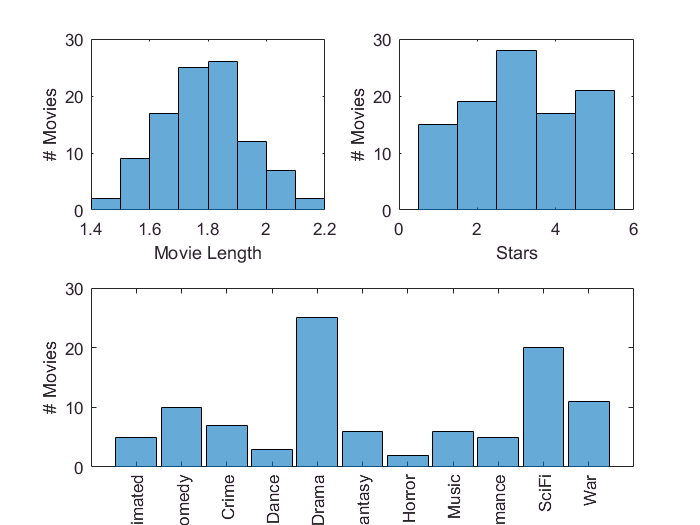

%% The movies
s = load('Movies.mat');
figure('Name','Movie Data')
subplot(2,2,1)
histogram(s.d.length)
xlabel('Movie Length')
ylabel('# Movies')
subplot(2,2,2)
histogram(s.d.rating)
xlabel('Stars')
ylabel('# Movies')
subplot(2,1,2)
histogram(categorical(s.d.genre))
ylabel('# Movies')
set(gca,'xticklabelrotation',90)

The viewer database is then created from the movie database:

%% The movie viewers
rng('default')
nViewers  = 4;
mvr       = MovieViewers( nViewers, s.d );

Next, we will displays the characteristics of the movies each viewer has watched. 

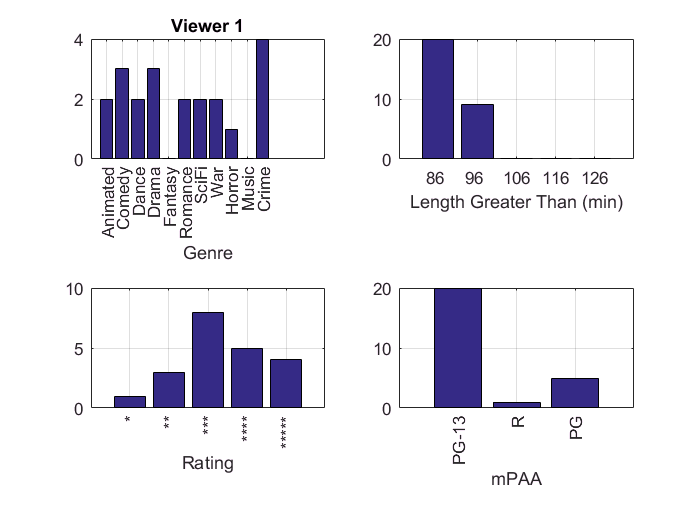

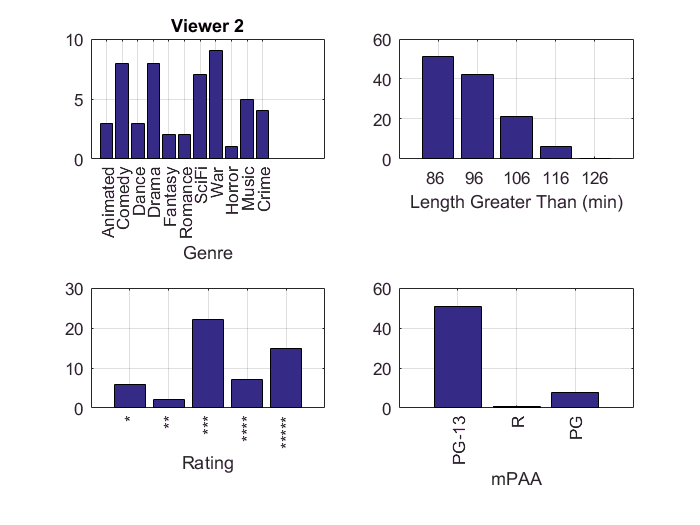

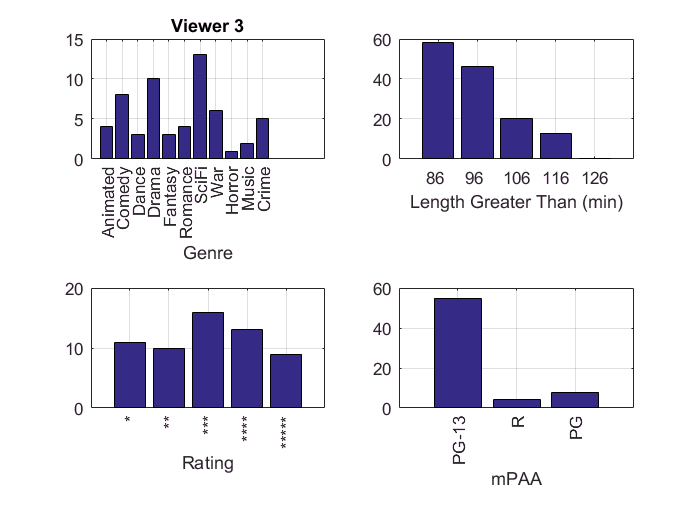

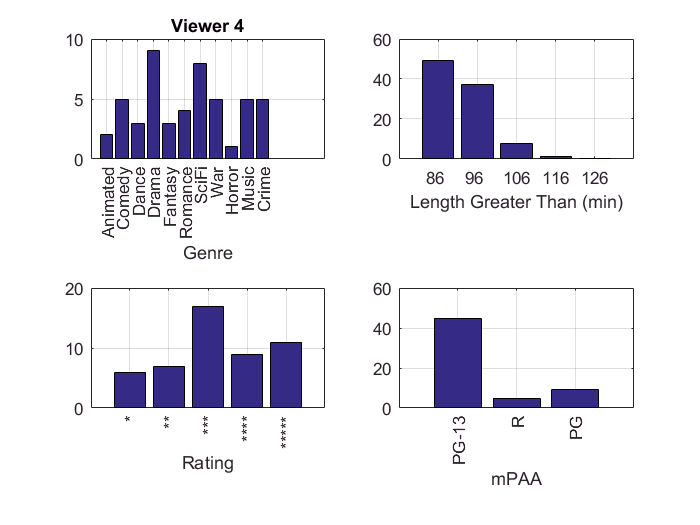

genre  = { 'Animated', 'Comedy', 'Dance', 'Drama', 'Fantasy', ...
           'Romance', 'SciFi', 'War', 'Horror', 'Music', 'Crime'};
mPAA   = {'PG-13','R','PG'};
rating = {'*' '**' '***' '****' '*****'};

% Display the movie viewer's data
lX     = linspace(min(s.d.length),max(s.d.length),5);

for k = 1:nViewers
  figure('Name', sprintf('Viewer %d',k));
  
  subplot(2,2,1);
  g = zeros(1,11);
  for j = 1:length(mvr{k})
    i     = mvr{k}(j);
    l     = strmatch(s.d.genre{i},genre); 
    g(l)  = g(l) + 1;
  end
  bar(1:11,g);
  set(gca,'xticklabel',genre,'xticklabelrotation',90,'xtick',1:11)
  xlabel('Genre')
  title(sprintf('Viewer %d',k))
  grid on
  
  subplot(2,2,2);
  g = zeros(1,5);
  for j = 1:5
    for i = 1:length(mvr{k})
      if( s.d.length(mvr{k}(i)) > lX(j) )
        g(j)  = g(j) + 1;
      end
    end
  end
  bar(1:5,g);
  set(gca,'xticklabel',floor(lX*60),'xtick',1:5)
  xlabel('Length Greater Than (min)')
  grid on
  
  subplot(2,2,3);
  g = zeros(1,5);
  for j = 1:length(mvr{k})
    i     = mvr{k}(j);
    l     = s.d.rating(i);
    g(l)  = g(l) + 1;
  end
  bar(1:5,g);
  set(gca,'xticklabel',rating,'xticklabelrotation',90,'xtick',1:5)
  xlabel('Rating')
  grid on
  
  subplot(2,2,4);
  g = zeros(1,3);
  for j = 1:length(mvr{k})
    i     = mvr{k}(j);
    l     = strmatch(s.d.mPAA{i},mPAA); 
    g(l)  = g(l) + 1;
  end
  bar(1:3,g);
  set(gca,'xticklabel',mPAA,'xticklabelrotation',90,'xtick',1:3)
  xlabel('mPAA')
  grid on
end

Next, We will train the neural net on a subset of the movies. This is a classification problem. We just want to know if a given movie would be picked or not picked by the viewer. We use `patternnet` to predict the movies watched. The input to `patternnet` is the sizes of the hidden layers, in this case, a single layer of size 25. We convert everything into integers. Note that you need to round the results since `patternnet` does not return integers, despite the label being an integer. `patternnet` has methods train and view.

rng('default')
%% Train and test the neural net for each viewer
for k = 1:nViewers
  % Create the training arrays  
  x = zeros(4,100); % the input data
  y = zeros(1,100); % the target - did the viewer watch the movie?
  
  nMov = length(mvr{k}); % number of watched movies
  for j = 1:nMov
    i      = mvr{k}(j); % index of the jth movie watched by the kth viewer
    x(1,j) = s.d.rating(i);
    x(2,j) = s.d.length(i);
    x(3,j) = strmatch(s.d.mPAA{i},mPAA,'exact'); %#ok<*MATCH3>
    x(4,j) = strmatch(s.d.genre{i},genre,'exact');
    y(1,j) = 1; % movie watched
  end
  
  i = setdiff(1:100,mvr{k}); % unwatched movies
  for j = 1:length(i)
    x(1,nMov+j) = s.d.rating(i(j));
    x(2,nMov+j) = s.d.length(i(j));
    x(3,nMov+j) = strmatch(s.d.mPAA{i(j)},mPAA,'exact'); 
    x(4,nMov+j) = strmatch(s.d.genre{i(j)},genre,'exact');
    y(1,nMov+j) = 0; % movie not watched
  end
  
  % Create the training and testing data
  j       = randperm(100);
  j       = j(1:70);  % train using 70% of the available data
  xTrain  = x(:,j);
  yTrain  = y(1,j);
  j       = setdiff(1:100,j);
	xTest   = x(:,j);
  yTest   = y(1,j);
  
  net     = patternnet(25); % input a scalar or row of layer sizes
  net     = train(net,xTrain,yTrain);
  view(net);
  yPred = round(net(xTest));
  
  %% Test the neural net
  accuracy = sum(yPred == yTest)/length(yTest);
  fprintf('Accuracy for viewer %d (%d movies watched) is %8.2f%%\n',...
    k,nMov,accuracy*100)
end

Accuracy for viewer 1 (21 movies watched) is    76.67%
Accuracy for viewer 2 (52 movies watched) is    60.00%
Accuracy for viewer 3 (59 movies watched) is    70.00%
Accuracy for viewer 4 (50 movies watched) is    90.00%


rng('default')
for k = 1:nViewers
  % Create the training arrays  
  x = zeros(4,100); % the input data
  y = zeros(1,100); % the target - did the viewer watch the movie?
  
  nMov = length(mvr{k}); % number of watched movies
  for j = 1:nMov
    i      = mvr{k}(j); % index of the jth movie watched by the kth viewer
    x(1,j) = s.d.rating(i);
    x(2,j) = s.d.length(i);
    x(3,j) = strmatch(s.d.mPAA{i},mPAA,'exact'); %#ok<*MATCH3>
    x(4,j) = strmatch(s.d.genre{i},genre,'exact');
    y(1,j) = 1; % movie watched
  end
  
  i = setdiff(1:100,mvr{k}); % unwatched movies
  for j = 1:length(i)
    x(1,nMov+j) = s.d.rating(i(j));
    x(2,nMov+j) = s.d.length(i(j));
    x(3,nMov+j) = strmatch(s.d.mPAA{i(j)},mPAA,'exact'); 
    x(4,nMov+j) = strmatch(s.d.genre{i(j)},genre,'exact');
    y(1,nMov+j) = 0; % movie not watched
  end
  
  % Create the training and testing data
  j       = randperm(100);
  j       = j(1:70);  % train using 70% of the available data
  xTrain  = x(:,j);
  yTrain  = y(1,j);
  j       = setdiff(1:100,j);
	xTest   = x(:,j);
  yTest   = y(1,j);
  
  net     = patternnet(15); % input a scalar or row of layer sizes
  net     = train(net,xTrain,yTrain);
  view(net);
  yPred = round(net(xTest));
  
  %% Test the neural net
  accuracy = sum(yPred == yTest)/length(yTest);
  fprintf('Accuracy for viewer %d (%d movies watched) is %8.2f%%\n',...
    k,nMov,accuracy*100)
end

Accuracy for viewer 1 (21 movies watched) is    76.67%
Accuracy for viewer 2 (52 movies watched) is    56.67%
Accuracy for viewer 3 (59 movies watched) is    76.67%
Accuracy for viewer 4 (50 movies watched) is    80.00%


rng('default')
for k = 1:nViewers
  % Create the training arrays  
  x = zeros(4,100); % the input data
  y = zeros(1,100); % the target - did the viewer watch the movie?
  
  nMov = length(mvr{k}); % number of watched movies
  for j = 1:nMov
    i      = mvr{k}(j); % index of the jth movie watched by the kth viewer
    x(1,j) = s.d.rating(i);
    x(2,j) = s.d.length(i);
    x(3,j) = strmatch(s.d.mPAA{i},mPAA,'exact'); %#ok<*MATCH3>
    x(4,j) = strmatch(s.d.genre{i},genre,'exact');
    y(1,j) = 1; % movie watched
  end
  
  i = setdiff(1:100,mvr{k}); % unwatched movies
  for j = 1:length(i)
    x(1,nMov+j) = s.d.rating(i(j));
    x(2,nMov+j) = s.d.length(i(j));
    x(3,nMov+j) = strmatch(s.d.mPAA{i(j)},mPAA,'exact'); 
    x(4,nMov+j) = strmatch(s.d.genre{i(j)},genre,'exact');
    y(1,nMov+j) = 0; % movie not watched
  end
  
  % Create the training and testing data
  j       = randperm(100);
  j       = j(1:70);  % train using 70% of the available data
  xTrain  = x(:,j);
  yTrain  = y(1,j);
  j       = setdiff(1:100,j);
	xTest   = x(:,j);
  yTest   = y(1,j);
  
  net     = patternnet(60); % input a scalar or row of layer sizes
  net     = train(net,xTrain,yTrain);
  view(net);
  yPred = round(net(xTest));
  
  %% Test the neural net
  accuracy = sum(yPred == yTest)/length(yTest);
  fprintf('Accuracy for viewer %d (%d movies watched) is %8.2f%%\n',...
    k,nMov,accuracy*100)
end

Accuracy for viewer 1 (21 movies watched) is    80.00%
Accuracy for viewer 2 (52 movies watched) is    63.33%
Accuracy for viewer 3 (59 movies watched) is    80.00%
Accuracy for viewer 4 (50 movies watched) is   100.00%


`patternnet(25)` returns good results (between 60%-90%), but we also tried greater and smaller numbers of layers and multiple hidden layers. For example, with a layer size of just 15, the accuracy ranges from 55% to 80%. With a size of 60, we almost reached ≥80% of all viewers! Granted, this is a small number of movies. The results will vary with each run due to the random nature of the variables in the test. Nonetheless, it does a good job of predicting movies that the viewer might like.